% setting
folder = 'C:\Users\bear\Desktop\figure 4';  
filename = 'matlab_mode'; % no need '_c{i}.tif'
outname = 'binuclear';
extension = '.tif';
num_channel = 4;
outname_csv = 'liver_temp.csv';

multichannel = import4d(folder, filename, extension, num_channel);

Finished importing channel 1
Finished importing channel 2
Finished importing channel 3
Finished importing channel 4


nucleus = multichannel(:, :, :, 1);
cellular = multichannel(:, :, :, 2);
cellular_mask = multichannel(:, :, :, 3);
nucleus_mask = multichannel(:, :, :, 4);

stats_cellular = regionprops3(cellular_mask, cellular, 'Centroid', 'Volume', 'EigenValues');
stats_nucleus = regionprops3(nucleus_mask, nucleus, 'Centroid', 'Volume', 'MeanIntensity');

stats_cellular_copy = stats_cellular;
stats_nucleus_copy = stats_nucleus;

stats_cellular = stats_cellular_copy;
stats_nucleus = stats_nucleus_copy;
stats_cellular = addvars(stats_cellular, (1:height(stats_cellular))', 'Before', 1, 'NewVariableNames', 'ID');
stats_nucleus = addvars(stats_nucleus, (1:height(stats_nucleus))', 'Before', 1, 'NewVariableNames', 'ID');

% identify which cell the nucleus belongs to
nuclei_centroids = stats_nucleus.Centroid;
cellular_for_nucleus = zeros(height(stats_nucleus), 1);
for i = 1:height(stats_nucleus)
    if ~any(isnan(nuclei_centroids(i,:)))
        x = round(nuclei_centroids(i,1)); % regionprops use xyz
        y = round(nuclei_centroids(i,2));
        z = round(nuclei_centroids(i,3));
        cellular_for_nucleus(i) = cellular_mask(y,x,z); % image use yxz 
    else
        disp(['Nucleus ' num2str(i) ': Contains NaN coordinates']);
        cellular_for_nucleus(i) = NaN;
    end
end

Nucleus 92: Contains NaN coordinates
Nucleus 430: Contains NaN coordinates
Nucleus 693: Contains NaN coordinates
Nucleus 821: Contains NaN coordinates
Nucleus 1069: Contains NaN coordinates
Nucleus 1212: Contains NaN coordinates
Nucleus 1301: Contains NaN coordinates
Nucleus 1324: Contains NaN coordinates
Nucleus 1589: Contains NaN coordinates
Nucleus 1899: Contains NaN coordinates
Nucleus 2207: Contains NaN coordinates
Nucleus 2370: Contains NaN coordinates
Nucleus 2555: Contains NaN coordinates
Nucleus 2568: Contains NaN coordinates
Nucleus 2579: Contains NaN coordinates
Nucleus 2580: Contains NaN coordinates
Nucleus 3155: Contains NaN coordinates
Nucleus 5242: Contains NaN coordinates
Nucleus 7756: Contains NaN coordinates
Nucleus 8139: Contains NaN coordinates
Nucleus 8200: Contains NaN coordinates
Nucleus 8215: Contains NaN coordinates
Nucleus 10060: Contains NaN coordinates
Nucleus 10439: Contains NaN coordinates
Nucleus 10647: Contains NaN coordinates
Nucleus 11263: Contains NaN


stats_nucleus = addvars(stats_nucleus, cellular_for_nucleus, 'Before', 2, 'NewVariableNames', 'CellularID');

% count number of nuclei
num_nuclei_per_cell = zeros(height(stats_cellular), 1);
for i = 1:height(stats_nucleus)
    cell_id = stats_nucleus.CellularID(i);
    if cell_id > 0 && ~isnan(cell_id)
        num_nuclei_per_cell(cell_id) = num_nuclei_per_cell(cell_id) + 1;
    end
end

stats_cellular = addvars(stats_cellular, num_nuclei_per_cell, 'Before', 2, 'NewVariableNames', 'NumNuclei');

% calculate nucleus volume and intensity
total_nucleus_volume_per_cell = zeros(height(stats_cellular), 1);
total_nucleus_intensity_per_cell = zeros(height(stats_cellular), 1);
for i = 1:height(stats_nucleus)
    cell_id = stats_nucleus.CellularID(i);
    if cell_id > 0 && ~isnan(cell_id)
        total_nucleus_volume_per_cell(cell_id) = total_nucleus_volume_per_cell(cell_id) + stats_nucleus.Volume(i);
        total_intensity = stats_nucleus.Volume(i) * stats_nucleus.MeanIntensity(i);
        total_nucleus_intensity_per_cell(cell_id) = total_nucleus_intensity_per_cell(cell_id) + total_intensity;
    end
end

stats_cellular = addvars(stats_cellular, ...
    total_nucleus_volume_per_cell, ...
    total_nucleus_intensity_per_cell, ...
    'Before', 2, ...
    'NewVariableNames', {'TotalNucleusVolume', 'TotalNucleusIntensity'});

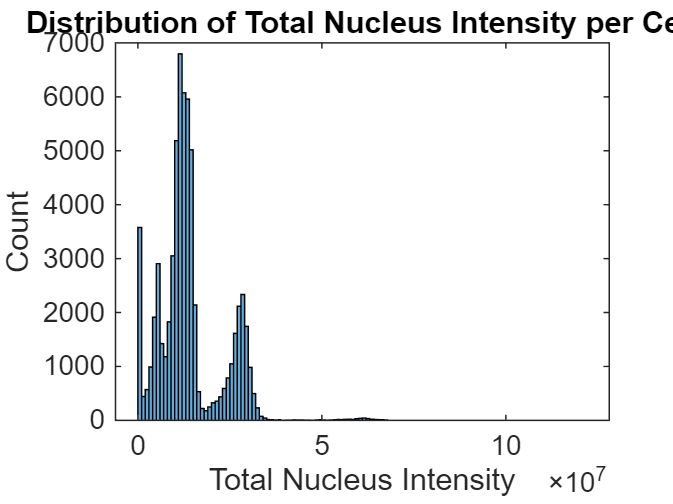

figure;
histogram(stats_cellular.TotalNucleusIntensity);
xlabel('Total Nucleus Intensity');
ylabel('Count');
title('Distribution of Total Nucleus Intensity per Cell');

% highlight by number of nuclei
lookup = zeros(max(cellular_mask(:)) + 1, 1, 'like', multichannel);  % +1 to include 0 index
lookup(2:height(stats_cellular)+1) = (stats_cellular.NumNuclei + 1) * 10000;
nucleus_count_image = lookup(cellular_mask + 1); % similar to dictionary

[y, x, z, c] = size(multichannel);
multichannel_new = zeros([y, x, z, c + 1], 'like', multichannel);
multichannel_new(:, :, :, 1) = nucleus;
multichannel_new(:, :, :, 2) = cellular;
multichannel_new(:, :, :, 3) = cellular_mask;
multichannel_new(:, :, :, 4) = nucleus_mask;
multichannel_new(:, :, :, 5) = nucleus_count_image;

export4d_float32(multichannel_new, 5, folder, outname, extension);

% extract necessary info
selected_table = stats_cellular(:, {'ID', 'Centroid', 'Volume', ...
    'EigenValues', 'TotalNucleusVolume', 'TotalNucleusIntensity', 'NumNuclei'});
writetable(selected_table, outname_csv);